load ('NeurotechsmilefrownangryblinkS1filt0p5notch56t64epochs.mat')
originalEEG = EEG

originalEEG = struct with fields:
             setname: 'smilefrownblinksam filt epochs'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: [2×39 char]
              nbchan: 2
              trials: 409
                pnts: 1000
               srate: 250
                xmin: -0.5000
                xmax: 3.4960
               times: [1×1000 double]
                data: [2×1000×409 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×2 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'common'
               event: [1×1746 struct]
             urevent: []
    eventdescription: {''  ''  ''  ''}
               epoch: [1×409 struct]
    epochdescription: {}
              reject: [1×1 struct]
               stats: [1×1 struct]



smileCat = (EEG.epochlabelscat=="S pressed");
sum(smileCat)

ans = 151

angryCat = (EEG.epochlabelscat=="A pressed");
sum(angryCat)

ans = 57



if sum(smileCat)>sum(angryCat)
    num_trials_per_cond = sum(angryCat)
else
    num_trials_per_cond = sum(smileCat)
end

num_trials_per_cond = 57

num_trials_per_cond

num_trials_per_cond = 57


idx_trialstokeep = [find(EEG.epochlabelscat=="S pressed",num_trials_per_cond) find(EEG.epochlabelscat=="A pressed",num_trials_per_cond)]

idx_trialstokeep =      7    10    11    13    14    17    18    20    21    22    23    24    32    33    34    35    40    41    43    44    49    50    51    52    58    59    60    72    73    74    75    76    77    78    79    80    81    82    91    93    95    97    99   101   103   104   105   106   107   108


idx_trialstokeep = sort(idx_trialstokeep);

EEG.data = originalEEG.data(:,:,idx_trialstokeep); %Trim the data
EEG.epochlabelscat = originalEEG.epochlabelscat(idx_trialstokeep); %Trim the list of labels
EEG.epochlabelscat = removecats(originalEEG.epochlabelscat(idx_trialstokeep)); %Remove extra categories
EEG.trials = sum(idx_trialstokeep);

for channel = 1:size(EEG.data,1)  
    %Trial by trial baseline removal
    EEG.data(channel,:, :) = EEG.data(channel,:, :) - mean(EEG.data(channel,:, :),2);
end

rng(101); % Do this to theoretically get the same split each time (not important for this situation, but important in my lab.)

% Hold out 20% of the data for the testing set.
ttpart = cvpartition(EEG.epochlabelscat,'HoldOut',.20);

% Set up table of data that includes the trial labels
traindata = table(EEG.epochlabelscat(ttpart.training)','VariableNames',{'labels'});

testdata = table(EEG.epochlabelscat(ttpart.test)','VariableNames',{'labels'});


includedchannels = [1 2]; %channels to included, this will calculate features for each separately 
timewindowforfeatures = [0 2000]; %start and stop in ms. If timepoints don't line up, this will select a slightly later time
timewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));

tempdata = traindata;
idxt = ttpart.training;

for ch = includedchannels
    clear mydata;
        mydata = squeeze(EEG.data(ch,timewindowepochidx,idxt));
end

[dataPoints, trialNum] = size(mydata)

dataPoints = 501

trialNum = 92

yk = zeros(dataPoints, trialNum);
trialMean = mean(mydata)

trialMean = 1×92 single row vector
    9.2102   -3.8001 -235.9464    8.2188 -104.0533   -2.4648    4.9798   28.4045   59.9688 -136.6710  -32.9192   -1.7878    6.4649   22.0821   -8.7055   -5.9050  -13.3713  -45.3971   -7.3019  -11.1326   -3.2275    2.9628    2.9162   -1.4094   -3.1361    0.8265    1.8149   30.2001  -98.2558   61.7417  -28.0090  141.8293 -236.7631   29.7540  -24.7806   18.6086  -20.0530    1.3306   -9.1199  -25.0543   17.0774   -6.2255  -18.2762    4.6821  -16.9176    0.1218   29.9726  -75.0659  -16.1305  -71.0080


yk = (cumsum((mydata)-mean(mydata)));

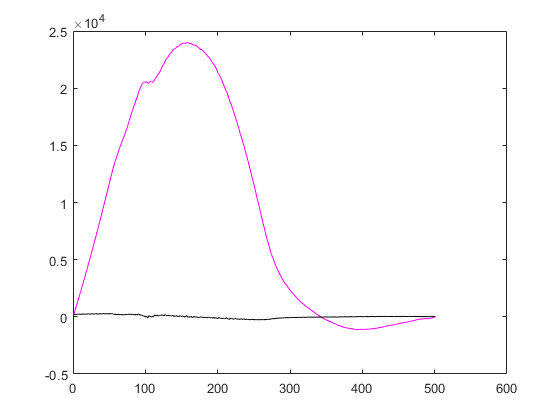

figure
plot(yk(:,78), 'm')
hold on
plot(mydata(:,78), 'k')
hold off

trialMean(78)

ans = single
16.1297

w.totaltimewindow = [1 dataPoints]; %start and stop data points, the size of each trial. If points don't line up, this will select a slightly later time
%timetimewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));

w.timewindowbinsize = [4 5 10 20 25 50]; %This is where you enter the different bin sizes that will be looped through. They should ideally divide into an equal number of data points
w.timewindowoverlap = 0; %128 for another paper

% includedchannels = 1:2;
% for ch = includedchannels    
%     for  tw = 1:size(w.alltimewindowsforfeatures,2)
%                     timewindowforfeatures = w.alltimewindowsforfeatures(:,tw);
%                     timewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));
%                     epochData = squeeze(EEG.data(ch,:,idxt)),2;
%     end
% end

for bin = 1:(size(w.timewindowbinsize,2))
    
    w.starttimes = w.totaltimewindow(1):(w.timewindowbinsize(bin)-w.timewindowoverlap):w.totaltimewindow(2);
    w.endtimes = (w.totaltimewindow(1)-1+w.timewindowbinsize(bin)):(w.timewindowbinsize(bin)-w.timewindowoverlap):w.totaltimewindow(2);
    if w.totaltimewindow(2) - w.starttimes(end) <= w.timewindowoverlap %if increment is smaller than the overlap window
        w.starttimes(end) = []; %then remove the last one (avoids indexing problem, plus you've already used this data)
    end
    if length(w.starttimes) > length(w.endtimes)
        w.endtimes = [w.endtimes w.totaltimewindow(2)];
        warning('The timewindowbinsize does not split evenly into the totaltimewindow, last window will be smaller')
        w.endtimes - w.starttimes
    end
    w.alltimewindowsforfeatures = [w.starttimes; w.endtimes];%(:,1) for first pair
    
    xval = [1:w.timewindowbinsize(bin)]
    
    for trial = 1:trialNum
        
            for L = 1:(w.totaltimewindow(2)/w.timewindowbinsize(bin))
                 databin = yk((w.starttimes(L):w.endtimes(L)), trialNum);
                 if L == 1
                    epochData = databin;
                 else
                    epochData = cat(2, epochData, databin); 
                 end
                
                epochData = [epochData databin];
            end
            
        if trial == 1
            epochTrial = epochData;
        else
            epochTrial = cat(3, epochTrial, epochData); 
        end
        
        for loop = 1:(w.totaltimewindow(2)/w.timewindowbinsize(bin))
            coeff(loop,:,trial) = polyfit(xval,epochTrial(1:(w.timewindowbinsize(bin)),loop,trial), 2);
            
            singleYn = polyval(coeff(loop,:,trial), xval);
            if loop == 1
                binYn = singleYn;
            else
                binYn = cat(2, binYn, singleYn); 
            end
        end
        
        if trial == 1
                yn = binYn;
            else
                yn = cat(3, yn, binYn); 
        end
    end
    
    squeeze(yn)
    yk = yk(1:(size(yn,2)),:) % When testing, yk ended up one row smaller than yn, so this makes yk and yn the same dimensions
    singleFn  = sqrt((sum((yk - squeeze(yn)).^2)/(size(yk,1))));
    if bin == 1
                fn = singleFn;
            else
                fn = cat(3, fn, singleFn); 
    end
end

xval =      1     2     3     4


Error using polyfit (line 44)
X and Y vectors must be the same size.

flucProfiles = squeeze(fn)
logFn = log10(flucProfiles)
logBinSize = log10(w.timewindowbinsize)

figure
plot(logBinSize, logFn(92,:), 'O')
p = polyfit(logBinSize,logFn(92,:),1)
f = polyval(p,logBinSize);
hold on
plot(logBinSize,f,'--r')
title('DFA from trial 92')
xlabel('log10(binSize)')
ylabel('log10(Fn)')
hold off

DFA = (mean((logFn./logBinSize)'))'

eegMFL = (log10(sqrt(sum((diff(mydata)).^2))))'
features = [table(DFA, eegMFL), traindata]

polyfit(xval,epochTrial(1:(w.timewindowbinsize(bin)),loop,trial), 2)